## Question 1

**1.1: ** We consider, as in **Assignment 1,** that the system is is subject to time varying delays taking three possible values τ0 = 0 (no delay), τ1 = 0.5h and τ2 = 1.5h. Consider the same controller K and implementation as in **Assignment 1.**

 We assume a model for the delays dictating that** τ1** appears a maximum of two consec utive times, and **τ0 **and **τ2** can only happen isolated. **E.g. τ1τ1τ2τ1τ1τ0τ2τ0**... is a valid sequence, while **τ1τ1τ2τ2τ0**... or **τ2τ0τ1τ1τ1**... are NOT valid sequences.

Provide the LMIs needed to verify the stability of your closed-loop system, and estimate the range of sampling intervals **h** for which the system is stable in this scenario.

% Define the range of allowed sampling intervals:
clear all;
clc;
h_values = 0.000001:0.000001:0.00001; % calculated from h << 2pi/|w| where |w| = 1 (from the desired closed loop poles).

% Desired poles (complex conjugate):
s1 = -2 + 1j;
s2 = -2 - 1j;

desiredPoles = [s1, s2];

% student id = 6492053

a = 6;
b = 9;
c = 3;

A = [0, 0.5+c; 0.5 + abs(a-b), 1];
B = [1 0]';

% Calculate the gain for the desired poles
K = place(A, B, desiredPoles);
Kn = [K 0];
stable_h = [];
unstable_h = [];

for i = 1:length(h_values)

    h = h_values(i);
    tau_0 = 0; tau_1 = 0.5*h; tau_2 = 1.5*h; % calculate the possible delays

    % Calculate F_tau1, G_tau1

    [F_tau0, G_tau0] = computeFG(A,B,tau_0,h);

    [F_tau1, G_tau1] = computeFG(A,B,tau_1,h);

    [F_tau2, G_tau2] = computeFG(A,B,tau_2,h);

    % Calculate rho

    rho0 = max(abs(eig(F_tau0 - G_tau0*Kn)))
    rho1 = max(abs(eig(F_tau1 - G_tau1*Kn)))
    rho2 = max(abs(eig(F_tau2 - G_tau2*Kn)))

    % Solve the LMIs:

    Q = eye(3);
    P = sdpvar(3,3);
    epsilon = 1e-6;
   
    cons = [P>=epsilon*eye(3,3), (F_tau0-G_tau0*Kn)'*P*(F_tau0-G_tau0*Kn) - P + Q <=0, (F_tau1-G_tau1*Kn)'*P*(F_tau1-G_tau1*Kn)- P + Q <=0, (F_tau2-G_tau2*Kn)'*P*(F_tau2-G_tau2*Kn) - P + Q <=0];
    obj = 0;
    result = optimize(cons,obj);

    %disp(result.info);

    %value(P);

end

rho0 = 1.0000

rho1 = 1.0000

rho2 = 1.0000

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 13, dim = 37, blocks = 5
nnz(A) = 91 + 0, nnz(ADA) = 36, nnz(L) = 21
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.77E+03 0.000
  1 :   0.00E+00 2.10E+02 0.000 0.0364 0.9900 0.9900  -2.60  1  1  1.6E+02
  2 :   0.00E+00 4.40E+01 0.000 0.2095 0.9000 0.9000  -1.01  1  1  1.7E+02
  3 :   0.00E+00 2.43E+00 0.000 0.0551 0.9900 0.9900  -1.01  1  1  2.1E+02
  4 :   0.00E+00 2.12E-01 0.000 0.0875 0.9900 0.9900  -0.99  1  1  2.1E+02
  5 :   0.00E+00 5.94E-02 0.000 0.2794 0.9000 0.9000  -0.89  1  1  1.8E+02
  6 :   0.00E+00 3.33E-03 0.000 0.0561 0.9900 0.9900  -0.84  1  1  2.8E+02
  7 :   0.00E+00 6.87E-04 0.000 0.2060 0.9000 0.9000  -1.23  1  1  3.2E+02
  8 :   0.00E+00 1.76E-04 0.000 0.2570 0.9000 0.9000  -1.14  1  1  7.1E+02
  9 :   0.00E+00 3.63E-05 0.000 0.2056 0.9000 0.9000  -1.25  1  1  8.3E+02
 10 :   0.00E+00 

rho0 = 1.0000

rho1 = 1.0000

rho2 = 1.0000

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 13, dim = 37, blocks = 5
nnz(A) = 91 + 0, nnz(ADA) = 36, nnz(L) = 21
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.77E+03 0.000
  1 :   0.00E+00 2.10E+02 0.000 0.0364 0.9900 0.9900  -2.60  1  1  1.6E+02
  2 :   0.00E+00 4.40E+01 0.000 0.2095 0.9000 0.9000  -1.01  1  1  1.7E+02
  3 :   0.00E+00 2.45E+00 0.000 0.0558 0.9900 0.9900  -1.01  1  1  2.1E+02
  4 :   0.00E+00 2.42E-01 0.000 0.0985 0.9900 0.9900  -0.98  1  1  2.0E+02
  5 :   0.00E+00 2.53E-02 0.000 0.1046 0.9450 0.9450  -0.79  1  1  1.5E+02
  6 :   0.00E+00 2.43E-03 0.429 0.0960 0.9900 0.9900  -1.10  1  1  2.6E+02
  7 :   0.00E+00 1.48E-03 0.000 0.6107 0.9000 0.9000  -1.27  1  1  3.0E+02
  8 :   0.00E+00 4.00E-04 0.000 0.2703 0.9000 0.9000  -1.31  1  1  4.4E+02
  9 :   0.00E+00 3.51E-05 0.000 0.0878 0.9900 0.9900  -1.27  1  1  6.9E+02
 10 :   0.00E+00 

rho0 = 1.0000

rho1 = 1.0000

rho2 = 1.0000

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 13, dim = 37, blocks = 5
nnz(A) = 91 + 0, nnz(ADA) = 36, nnz(L) = 21
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.77E+03 0.000
  1 :   0.00E+00 2.10E+02 0.000 0.0364 0.9900 0.9900  -2.60  1  1  1.6E+02
  2 :   0.00E+00 4.40E+01 0.000 0.2095 0.9000 0.9000  -1.01  1  1  1.7E+02
  3 :   0.00E+00 2.48E+00 0.000 0.0564 0.9900 0.9900  -1.01  1  1  2.1E+02
  4 :   0.00E+00 4.83E-01 0.000 0.1944 0.9000 0.9000  -0.97  1  1  2.0E+02
  5 :   0.00E+00 1.11E-01 0.000 0.2303 0.9000 0.9000  -0.84  1  1  1.7E+02
  6 :   0.00E+00 5.37E-03 0.000 0.0483 0.9900 0.9900  -0.94  1  1  3.1E+02
  7 :   0.00E+00 1.61E-03 0.000 0.2989 0.9000 0.9000  -1.21  1  1  3.1E+02
  8 :   0.00E+00 6.67E-04 0.000 0.4157 0.9000 0.9000  -1.49  1  1  3.7E+02
  9 :   0.00E+00 1.74E-04 0.000 0.2614 0.9000 0.9000  -1.31  1  1  4.2E+02
 10 :   0.00E+00 

rho0 = 1.0000

rho1 = 1.0000

rho2 = 1.0000

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 13, dim = 37, blocks = 5
nnz(A) = 91 + 0, nnz(ADA) = 36, nnz(L) = 21
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.77E+03 0.000
  1 :   0.00E+00 2.10E+02 0.000 0.0364 0.9900 0.9900  -2.60  1  1  1.6E+02
  2 :   0.00E+00 4.40E+01 0.000 0.2095 0.9000 0.9000  -1.01  1  1  1.7E+02
  3 :   0.00E+00 2.51E+00 0.000 0.0571 0.9900 0.9900  -1.01  1  1  2.1E+02
  4 :   0.00E+00 5.26E-01 0.000 0.2096 0.9000 0.9000  -0.96  1  1  1.9E+02
  5 :   0.00E+00 8.94E-02 0.000 0.1698 0.9000 0.9000  -0.81  1  1  1.6E+02
  6 :   0.00E+00 4.27E-03 0.000 0.0477 0.9900 0.9900  -1.02  1  1  3.6E+02
  7 :   0.00E+00 2.05E-03 0.000 0.4805 0.9000 0.9000  -1.22  1  1  4.4E+02
  8 :   0.00E+00 5.33E-04 0.000 0.2601 0.9000 0.9000  -1.37  1  1  5.8E+02
  9 :   0.00E+00 5.00E-05 0.000 0.0938 0.9900 0.9900  -1.22  1  1  6.5E+02
 10 :   0.00E+00 

rho0 = 1.0000

rho1 = 1.0000

rho2 = 1.0000

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 13, dim = 37, blocks = 5
nnz(A) = 91 + 0, nnz(ADA) = 36, nnz(L) = 21
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.77E+03 0.000
  1 :   0.00E+00 2.10E+02 0.000 0.0364 0.9900 0.9900  -2.60  1  1  1.6E+02
  2 :   0.00E+00 4.40E+01 0.000 0.2095 0.9000 0.9000  -1.01  1  1  1.7E+02
  3 :   0.00E+00 2.54E+00 0.000 0.0577 0.9900 0.9900  -1.00  1  1  2.1E+02
  4 :   0.00E+00 5.70E-01 0.000 0.2242 0.9000 0.9000  -0.95  1  1  1.9E+02
  5 :   0.00E+00 6.48E-02 0.000 0.1137 0.9450 0.9450  -0.80  1  1  1.6E+02
  6 :   0.00E+00 7.19E-03 0.000 0.1111 0.9450 0.9450  -1.09  1  1  2.3E+02
  7 :   0.00E+00 2.99E-03 0.000 0.4150 0.9000 0.9000  -1.21  1  1  2.6E+02
  8 :   0.00E+00 9.39E-04 0.000 0.3144 0.9000 0.9000  -1.38  1  1  3.3E+02
  9 :   0.00E+00 2.03E-04 0.000 0.2166 0.9000 0.9000  -1.25  1  1  3.7E+02
 10 :   0.00E+00 

rho0 = 1.0000

rho1 = 1.0000

rho2 = 1.0000

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 13, dim = 37, blocks = 5
nnz(A) = 91 + 0, nnz(ADA) = 36, nnz(L) = 21
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.77E+03 0.000
  1 :   0.00E+00 2.10E+02 0.000 0.0364 0.9900 0.9900  -2.60  1  1  1.6E+02
  2 :   0.00E+00 4.40E+01 0.000 0.2095 0.9000 0.9000  -1.01  1  1  1.7E+02
  3 :   0.00E+00 2.57E+00 0.000 0.0584 0.9900 0.9900  -1.00  1  1  2.0E+02
  4 :   0.00E+00 6.10E-01 0.000 0.2372 0.9000 0.9000  -0.94  1  1  1.9E+02
  5 :   0.00E+00 6.37E-02 0.000 0.1045 0.9450 0.9450  -0.79  1  1  1.7E+02
  6 :   0.00E+00 6.59E-03 0.000 0.1035 0.9450 0.9450  -1.10  1  1  2.6E+02
  7 :   0.00E+00 2.64E-03 0.000 0.3997 0.9000 0.9000  -1.18  1  1  3.4E+02
  8 :   0.00E+00 6.86E-04 0.000 0.2602 0.9000 0.9000  -1.32  1  1  4.4E+02
  9 :   0.00E+00 1.48E-04 0.000 0.2154 0.9000 0.9000  -1.20  1  1  4.6E+02
 10 :   0.00E+00 

rho0 = 1.0000

rho1 = 1.0000

rho2 = 1.0000

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 13, dim = 37, blocks = 5
nnz(A) = 91 + 0, nnz(ADA) = 36, nnz(L) = 21
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.77E+03 0.000
  1 :   0.00E+00 2.10E+02 0.000 0.0364 0.9900 0.9900  -2.60  1  1  1.6E+02
  2 :   0.00E+00 4.40E+01 0.000 0.2095 0.9000 0.9000  -1.01  1  1  1.7E+02
  3 :   0.00E+00 2.60E+00 0.000 0.0591 0.9900 0.9900  -1.00  1  1  2.0E+02
  4 :   0.00E+00 6.46E-01 0.000 0.2482 0.9000 0.9000  -0.93  1  1  1.9E+02
  5 :   0.00E+00 4.74E-02 0.000 0.0734 0.9900 0.9900  -0.79  1  1  1.7E+02
  6 :   0.00E+00 7.92E-03 0.000 0.1671 0.9000 0.9000  -1.16  1  1  2.3E+02
  7 :   0.00E+00 2.52E-03 0.000 0.3184 0.9000 0.9000  -1.12  1  1  3.1E+02
  8 :   0.00E+00 7.31E-04 0.000 0.2897 0.9000 0.9000  -1.31  1  1  3.9E+02
  9 :   0.00E+00 1.82E-04 0.000 0.2494 0.9000 0.9000  -1.23  1  1  4.1E+02
 10 :   0.00E+00 

rho0 = 1.0000

rho1 = 1.0000

rho2 = 1.0000

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 13, dim = 37, blocks = 5
nnz(A) = 91 + 0, nnz(ADA) = 36, nnz(L) = 21
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.77E+03 0.000
  1 :   0.00E+00 2.10E+02 0.000 0.0364 0.9900 0.9900  -2.60  1  1  1.6E+02
  2 :   0.00E+00 4.40E+01 0.000 0.2095 0.9000 0.9000  -1.01  1  1  1.7E+02
  3 :   0.00E+00 2.63E+00 0.000 0.0599 0.9900 0.9900  -1.00  1  1  2.0E+02
  4 :   0.00E+00 6.78E-01 0.000 0.2572 0.9000 0.9000  -0.92  1  1  1.8E+02
  5 :   0.00E+00 4.90E-02 0.000 0.0724 0.9900 0.9900  -0.79  1  1  1.9E+02
  6 :   0.00E+00 5.64E-03 0.000 0.1150 0.9450 0.9450  -1.16  1  1  3.1E+02
  7 :   0.00E+00 1.62E-03 0.242 0.2875 0.9000 0.9000  -1.11  1  1  6.5E+02
  8 :   0.00E+00 5.15E-04 0.000 0.3177 0.9000 0.9000  -1.29  1  1  7.9E+02
  9 :   0.00E+00 1.53E-04 0.000 0.2976 0.9000 0.9000  -1.12  1  1  8.0E+02
 10 :   0.00E+00 

rho0 = 1.0000

rho1 = 1.0000

rho2 = 1.0000

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 13, dim = 37, blocks = 5
nnz(A) = 91 + 0, nnz(ADA) = 36, nnz(L) = 21
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.77E+03 0.000
  1 :   0.00E+00 2.10E+02 0.000 0.0364 0.9900 0.9900  -2.60  1  1  1.6E+02
  2 :   0.00E+00 4.40E+01 0.000 0.2095 0.9000 0.9000  -1.01  1  1  1.7E+02
  3 :   0.00E+00 2.67E+00 0.000 0.0606 0.9900 0.9900  -1.00  1  1  2.0E+02
  4 :   0.00E+00 7.05E-01 0.000 0.2641 0.9000 0.9000  -0.92  1  1  1.8E+02
  5 :   0.00E+00 4.57E-02 0.000 0.0649 0.9900 0.9900  -0.80  1  1  2.1E+02
  6 :   0.00E+00 7.49E-03 0.000 0.1638 0.9000 0.9000  -1.18  1  1  2.8E+02
  7 :   0.00E+00 1.63E-03 0.052 0.2172 0.9000 0.9000  -1.06  1  1  6.0E+02
  8 :   0.00E+00 4.36E-04 0.000 0.2678 0.9000 0.9000  -1.35  1  1  7.9E+02
  9 :   0.00E+00 9.32E-05 0.000 0.2140 0.9000 0.9000  -1.10  1  1  7.9E+02
 10 :   0.00E+00 

rho0 = 1.0000

rho1 = 1.0000

rho2 = 1.0000

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 13, dim = 37, blocks = 5
nnz(A) = 91 + 0, nnz(ADA) = 36, nnz(L) = 21
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.77E+03 0.000
  1 :   0.00E+00 2.10E+02 0.000 0.0364 0.9900 0.9900  -2.60  1  1  1.6E+02
  2 :   0.00E+00 4.40E+01 0.000 0.2095 0.9000 0.9000  -1.01  1  1  1.7E+02
  3 :   0.00E+00 2.70E+00 0.000 0.0614 0.9900 0.9900  -1.00  1  1  2.0E+02
  4 :   0.00E+00 7.26E-01 0.000 0.2689 0.9000 0.9000  -0.91  1  1  1.8E+02
  5 :   0.00E+00 3.96E-02 0.000 0.0546 0.9900 0.9900  -0.82  1  1  2.4E+02
  6 :   0.00E+00 7.40E-03 0.000 0.1867 0.9000 0.9000  -1.20  1  1  3.0E+02
  7 :   0.00E+00 1.66E-03 0.143 0.2242 0.9000 0.9000  -1.06  1  1  6.4E+02
  8 :   0.00E+00 5.70E-04 0.000 0.3435 0.9000 0.9000  -1.34  1  1  7.6E+02
  9 :   0.00E+00 1.31E-04 0.000 0.2306 0.9000 0.9000  -1.12  1  1  7.7E+02
 10 :   0.00E+00 

function [F, G] = computeFG(A,B,tau,h)

f = @(s) expm(A*s) * B;

% Define the discrete time system:

Fx = expm(A*h);


if tau < h
    Fu = integral(@(s) f(s), h-tau, h, 'ArrayValued',true);
    G1 = integral(@(s) f(s), 0, h-tau, 'ArrayValued',true);
elseif tau >=h && tau <2*h
    Fu = integral(@(s) f(s), 0, 2*h-tau, 'ArrayValued',true);
    G1 = [0 0]';
elseif tau == 0
    G1 = integral(@(s) f(s), 0, h, 'ArrayValued',true);
    Fu = [0 0]';
else
    Fu = [0 0]';
    G1 = [0 0]';
end

F = [Fx Fu; zeros(1,3)];
G = [G1; 1];

end


taus = linspace(1.5*h, 2*h, 200000);

unstable = true;

% Desired poles (complex conjugate):
s1 = -2 + 1j;
s2 = -2 - 1j;

desiredPoles = [s1, s2];

% student id = 6492053

a = 6;
b = 9;
c = 3;

A = [0, 0.5+c; 0.5 + abs(a-b), 1];
B = [1 0]';

% Calculate the gain for the desired poles
K = place(A, B, desiredPoles);

Kn = [K 0];

for j = 1:length(taus)

    tau = taus(j);

    [F,G] = computeFG(A,B,tau,h);

    Fcl = F - G*Kn; % or construct full augmented matrix properly
    rho = max(abs(eig(Fcl)));

    if rho < 1
        unstable = false;
        break;
    end

end

if unstable
    disp("System is unstable for all tau >= 1.5h")
else
    disp("There exists stabilizing tau in the interval")
end

System is unstable for all tau >= 1.5h


## Question 3

We assume that the system is affected by a constant small delay τ ∈ [0,h). Employ the so-called Jordan form approach (as in Lecture 4) to construct a poly topic discrete-time model over-approximating the uncertain exact discrete-time closed loop NCS dynamics:


clear; clc;

a = 6;
b = 9;
c = 3;

A = [0, 0.5+c; 0.5 + abs(a-b), 1];
B = [1 0]';

desiredPoles = [-2 -3];
K = place(A,B,desiredPoles);
Kn = [K 0];

[V,D] = eig(A);
l1 = D(1,1);
l2 = D(2,2);

con = 3.5/(l1 - l2);

h_values   = 0.1:0.05:1;
tau_values = 0:0.01:1;

stable_map = zeros(length(h_values), length(tau_values));

for i = 1:length(h_values)

    h = h_values(i);

    Fx = expm(A*h);

    alpha1_L = 1;
    alpha1_U = exp(l1*h);

    alpha2_L = exp(l2*h);
    alpha2_U = 1;

    F0 = [con*(exp(l2*h)/l2 - exp(l1*h)/l1);
          (con/3.5)*(exp(l2*h) - exp(l1*h))];

    F1 = [con/l1;
          con/3.5];

    F2 = [-con/l2;
          -con/3.5];

    Fu1 = F0 + alpha1_L*F1 + alpha2_L*F2;
    Fu2 = F0 + alpha1_L*F1 + alpha2_U*F2;
    Fu3 = F0 + alpha1_U*F1 + alpha2_L*F2;
    Fu4 = F0 + alpha1_U*F1 + alpha2_U*F2;

    F1_aug = [Fx, Fu1; zeros(1,size(Fx,1)), 0];
    F2_aug = [Fx, Fu2; zeros(1,size(Fx,1)), 0];
    F3_aug = [Fx, Fu3; zeros(1,size(Fx,1)), 0];
    F4_aug = [Fx, Fu4; zeros(1,size(Fx,1)), 0];

    G1_aug = [zeros(size(Fx,1),1); 1];
    G2_aug = [zeros(size(Fx,1),1); 1];
    G3_aug = [zeros(size(Fx,1),1); 1];
    G4_aug = [zeros(size(Fx,1),1); 1];

    n = size(F1_aug,1);
    P = sdpvar(n,n);

    cons = [P >= 1e-6*eye(n)];

    Hcl1 = F1_aug - G1_aug*Kn;
    Hcl2 = F2_aug - G2_aug*Kn;
    Hcl3 = F3_aug - G3_aug*Kn;
    Hcl4 = F4_aug - G4_aug*Kn;

    gamma = 0.00001;

    cons = [cons, Hcl1'*P*Hcl1 - P <= -gamma*P];
    cons = [cons, Hcl2'*P*Hcl2 - P <= -gamma*P];
    cons = [cons, Hcl3'*P*Hcl3 - P <= -gamma*P];
    cons = [cons, Hcl4'*P*Hcl4 - P <= -gamma*P];

    sol = optimize(cons);

    isStable = (sol.problem == 0);

    stable_map(i,:) = isStable;

end

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 16, dim = 46, blocks = 6
nnz(A) = 123 + 0, nnz(ADA) = 36, nnz(L) = 21
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.76E+04 0.000
  1 :   0.00E+00 1.12E+03 0.000 0.0405 0.9900 0.9900   1.00  1  1  2.7E+01
  2 :   0.00E+00 3.62E+02 0.000 0.3236 0.9000 0.9000   1.00  1  1  8.7E+00
  3 :   0.00E+00 1.17E+02 0.000 0.3232 0.9000 0.9000   1.00  1  1  2.8E+00
  4 :   0.00E+00 3.03E+01 0.000 0.2588 0.9000 0.9000   1.00  1  1  7.3E-01
  5 :   0.00E+00 6.35E+00 0.000 0.2098 0.9000 0.9000   0.98  1  1  1.6E-01
  6 :   0.00E+00 1.37E+00 0.000 0.2163 0.9000 0.9000   0.92  1  1  3.6E-02
  7 :   0.00E+00 3.07E-01 0.000 0.2235 0.9000 0.9000   0.68  1  1  1.0E-02
  8 :   0.00E+00 6.96E-02 0.000 0.2266 0.9000 0.9000   0.06  1  1  5.3E-03
  9 :   0.00E+00 1.53E-02 0.000 0.2193 0.9000 0.9000  -0.61  1  1  4.7E-03
 10 :   0.00E+00

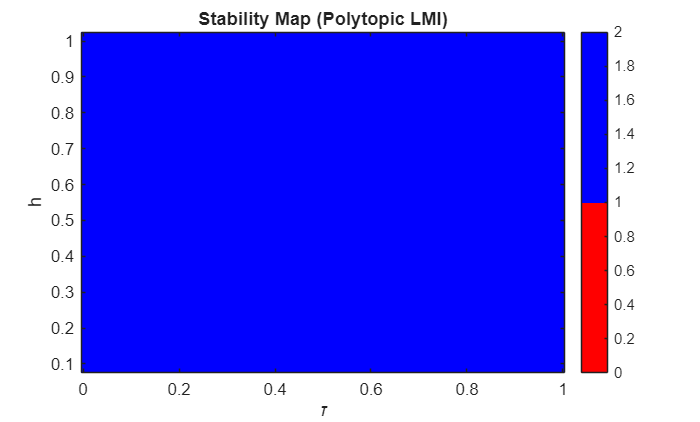


figure;
imagesc(tau_values, h_values, stable_map);
set(gca,'YDir','normal');
colormap([1 0 0; 0 0 1]);
xlabel('\tau');
ylabel('h');
title('Stability Map (Polytopic LMI)');
colorbar;